# SEIQR Model Simulation

Copyright 2022 Justice Inkoom at University of Mines and Technology

This is a simple **SEIQR** model of disease spread, implemented in MATLAB®. This approach is widely used to analyze infection data during the different stages of an epidemic outbreak. The population is divided into Susceptible (S), Exposed (E), Infectious (I), Quarantined (Q), and Recovered (R) individuals.

This particular model with its parameters are based on covid-19 outbreak in Ghana.

## The Model Overview

The equations that make up the SEIQR model are described by 5 ordinary differential equations as follows:


$$\begin{array}{l}
\frac{\mathrm{ds}}{\mathrm{dt}}=-\beta \ldotp s\ldotp i\\
\frac{\mathrm{de}}{\mathrm{dt}}=\beta \ldotp s\ldotp i-\alpha \ldotp e\\
\frac{\mathrm{di}}{\mathrm{dt}}=\alpha \ldotp e-\gamma \ldotp i\\
\frac{\mathrm{dr}}{\mathrm{dt}}=\gamma \ldotp i
\end{array}$$


## Model Simulation

**Model Parameters**

Play around with the parameters using the sliders and see the effect on the plot.

%% Initial parameters
%% Initial parameters
a = 0.14;     %rate at which a baby is born into a susceptible class
B = 0.6;     %exrate at which a person is exposed to the Covid-19 infection
g = 0.34;     %rate at which an exposed persone becomes infected with Covid-19 virus
s0 = 0.8;          %initial proportion of Susceptible
e0 = 0;   %initial proportion of Exposed
i0 = 0.2;   %initial proportion of Infected
r0 = 0;   %initial proportion of Recovered

**Solve the ODE using **[ode45](https://www.mathworks.com/help/matlab/ref/ode45.html).

y0 = [s0; e0; i0; r0];                % Initial conditions
T = 30;
tspan = [0 T];                        % Interval of Integration
[t,y] = ode45(@(t,y) seir_model(t,y,a,B,g),tspan,y0);

For more info see the [Anonymous functions documentation](http://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html).

**Plots that show the results**

t

t =          0
    0.0005
    0.0010
    0.0016
    0.0021
    0.0047
    0.0073
    0.0099
    0.0126
    0.0256


y

y =     0.8000         0    0.2000         0
    0.7999    0.0001    0.2000    0.0000
    0.7999    0.0001    0.1999    0.0001
    0.7998    0.0002    0.1999    0.0001
    0.7998    0.0002    0.1999    0.0001
    0.7995    0.0005    0.1997    0.0003
    0.7993    0.0007    0.1995    0.0005
    0.7990    0.0010    0.1993    0.0007
    0.7988    0.0012    0.1991    0.0009
    0.7976    0.0024    0.1983    0.0017


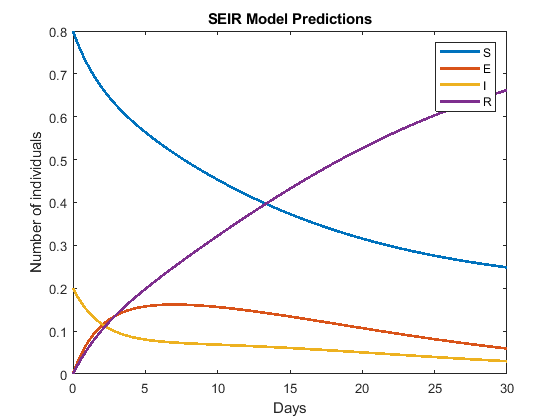

plot(t,y,'LineWidth',2);
xlabel('Days'); 
ylabel('Number of individuals');
legend('S','E','I','R');
title('SEIR Model Predictions');

For more info see the [plot documentation](https://www.mathworks.com/help/matlab/ref/plot.html).

**Function **`seir_model`** that calculates the model evolution over a time period T.**

function dydt = seir_model(t,y,a,B,g)
  S = y(1);
  E = y(2);
  I = y(3);
  R = y(4);
  % Equations of the model described above
  dS = (-B*S*I) ;
  dE = ((B*S*I)-(a*E)) ;
  dI = ((a*E)-(g*I));
  dR = (g*I);
  dydt = [dS;dE;dI;dR];
end

## Further Evaluation

The three critical parameters in the model are beta, lambda and gamma.

Note that we have left several features unmodeled, for example: 

- Immunity loss rate ($\left.\alpha \right)$, where recovered individuals can get infected again.

- Some exposed individuals in "E" might move directly to the "R" category;

-  Some infected individuals in category "I" might not gain perfect immunity and so may move back to susceptible category "S." 

Despite these limitations, this basic SEIR model can provide some useful insights on the disease evolution.

  **Task.** Include additional features to your model and observe the effect on the plot.

                Example: To include Immunity loss rate ($\left.\alpha \right)$, the equations will be as follows:

                
$$\begin{array}{l}
\frac{\mathrm{dS}}{\mathrm{dt}}=-\beta \cdot \mathrm{S}\cdot \frac{I}{N}+\alpha \cdot \mathrm{R}\\
\frac{\mathrm{dE}}{\mathrm{dt}}=\beta \cdot \mathrm{S}\cdot \frac{I}{N}-\lambda \cdot E\\
\frac{\mathrm{dI}}{\mathrm{dt}}=\lambda \cdot E-\gamma \cdot \mathrm{I}\\
\frac{\mathrm{dR}}{\mathrm{dt}}=\gamma \cdot \mathrm{I}-\alpha \cdot \mathrm{R}
\end{array}$$
